clear variables;

Signal p

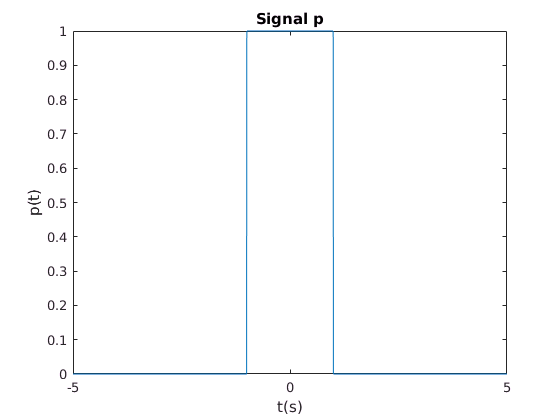

D=5;
N=2000;
T=2;
t=[-D:2*D/N:D];

p = abs(t/T)<1/2;

figure(1)
plot(t,p)
title('Signal p')
xlabel('t(s)')
ylabel('p(t)')

Transformée de Fourier

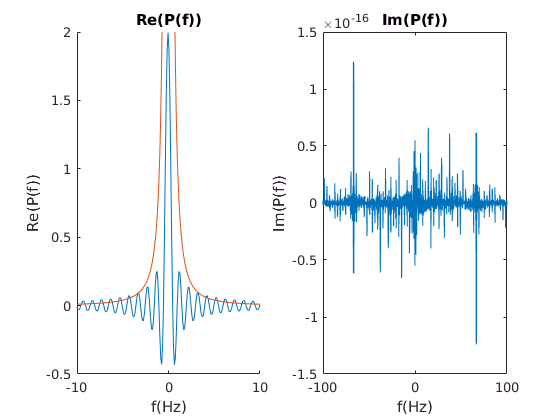

[P,f] = TransFourier(p,t);

u = 1./(f.^2);

figure(2);
subplot(121);
hold on
plot(f,real(P));
plot(f,u)

axis([-10 10 -0.5 2])
title('Re(P(f))')
xlabel('f(Hz)')
ylabel('Re(P(f))')
subplot(122);
plot(f,imag(P));
title('Im(P(f))')
xlabel('f(Hz)')
ylabel('Im(P(f))')

Le signal p est paire (car la fonction porte est elle-même paire). Or, une fonction paire en Fourier n'est pas complexe (Partie imaginaire nulle).

P(f) est complexe car Matlab utilise une approximation de la transformée de Fourier (approximation des trapèzes) : c'est pourquoi la partie imaginaire de P(f) n'est pas nulle mais très petite (10^-16)

On relève 1.995 en amplitude maximale soit environ T. Cela s'explique par la théorie avec la formule du changement d'échelle, la transformée de Fourier à l'origine est égale à AT (sinc(fT) = 0 car f = 0, A est l'amplitude de p soit 1) soit 1*2 = 2. La valeur relevée est bien cohérente avec la théorie.

Pour la période, avec le module au carré de P, on relève f1 = -0.5497 Hz et f2 = -1.049 Hz soit deltaf = 0.4493 Hz . Cela s'explique par le changement d'échelle avec T = 2 s, on a bien 1/T = 0.5 Hz. La valeur relevée est bien cohérente avec la théorie.

La décroissance correspond à une courbe de 1./(f.^2)

La bande spectrale est finie car on a une fonction porte.

Densité spectrale d'énergie du signal p

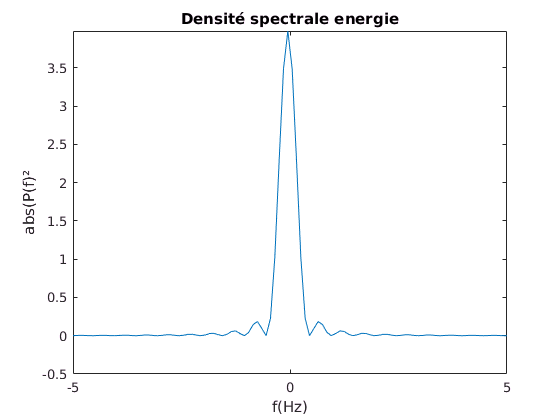

Gamma = abs(P).^2;

figure(3)
plot(f, Gamma)
axis([-5 5 -0.5 +inf])
title('Densité spectrale energie')
xlabel('f(Hz)')
ylabel('abs(P(f)²')

Pour le lobe primaire, on a 0.4498 Hz et la valeur théorique est 1/T = 0.5 Hz

Pour le 1er lobe secondaire, on a 0.9495 Hz et la valeur théorique est 2/T = 1 Hz

Pour le 2eme lobe secondaire, on a 1.449 Hz et la valeur théorique est 3/T = 1.5 Hz

Pour le 3eme lobe secondaire, on a 1.949 Hz et la valeur théorique est 4/T = 2 Hz

Les valeurs expérimentales sont cohérentes avec les valeurs théoriques.

Signal p(t-t0)

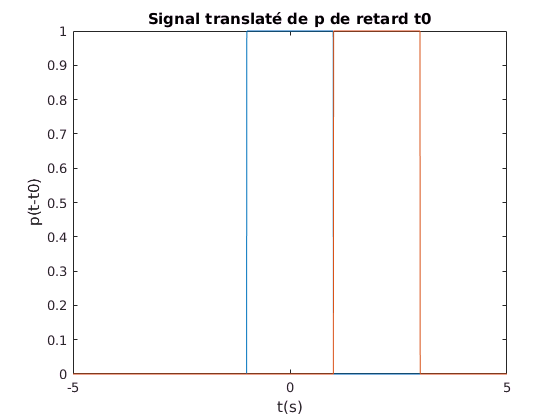

retard = 2;

p2= abs((t-retard)/T)<1/2;

figure(4)
plot(t,p)
title('Signal p')
xlabel('t(s)')
ylabel('p(t)')
hold on

plot(t,p2)
title('Signal translaté de p de retard t0')
xlabel('t(s)')
ylabel('p(t-t0)')

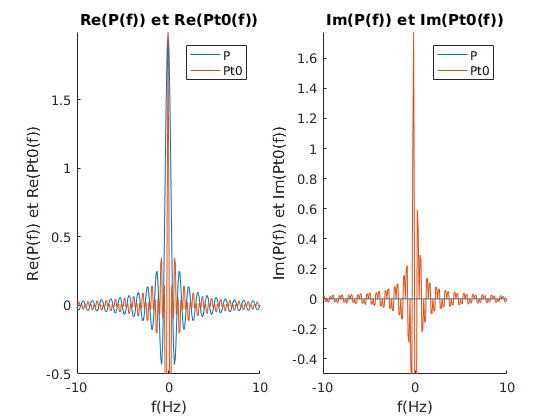

[P2,f] = TransFourier(p2,t);

figure(5)

subplot(121);
hold on
plot(f,real(P));
plot(f,real(P2));
legend('P', 'Pt0')
axis([-10 10 -0.5 +inf])
title('Re(P(f)) et Re(Pt0(f))')
xlabel('f(Hz)')
ylabel('Re(P(f)) et Re(Pt0(f))')

subplot(122);
hold on
plot(f,imag(P));
plot(f,imag(P2));
legend('P', 'Pt0');
axis([-10 10 -0.5 +inf])
title('Im(P(f)) et Im(Pt0(f))')
xlabel('f(Hz)')
ylabel('Im(P(f)) et Im(Pt0(f))')

Le signal Pt0(f) ne devrait pas être réelle car avec la formule de translation, on obtient un exp(-2*i*pi*f*t) ce qui fait que la partie réelle doit être nulle.

Signal pA(t)

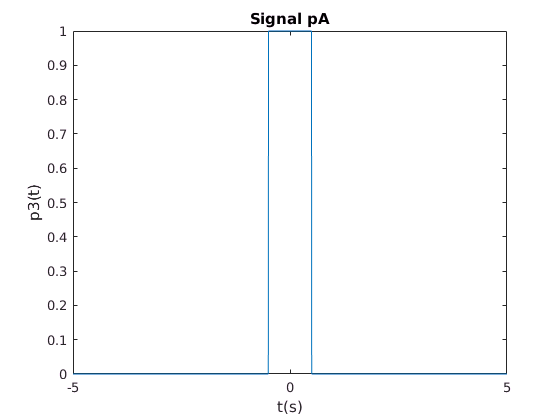

echelle = 2;

p3= abs(echelle*(t/T))<1/2;

figure(6)
plot(t,p3)
title('Signal pA')
xlabel('t(s)')
ylabel('p3(t)')